% Experiment on the Cascaded watertanks benchmark
%
% References
% ---------
%
% A Tensor Network Kalman filter with an application in recursive MIMO Volterra system identification
% 2016, Kim Batselier, Zhongming Chen, Ngai Wong
% 

clear all
close all
clc

%for reproducibility
rng(1);

% load('silverbox\Schroeder80mV.mat')


load('silverbox\SNLS80mV.mat')

V1=((V1-mean(V1))/0.4+0.5)'; % Remove offset errors on the input measurements (these are visible in the zero sections of the input)
                % The input is designed to have zero mean
V2=((V2-mean(V2))/0.7+0.5)';

Preprocessing Data

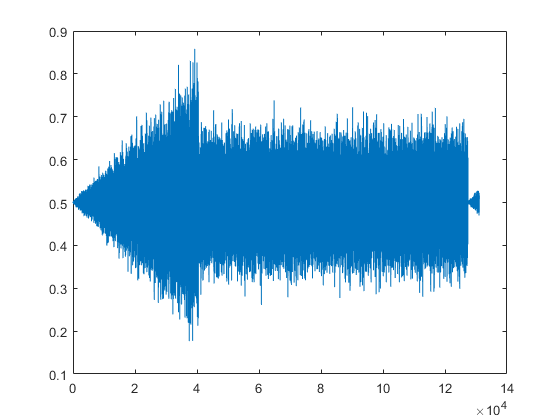


V1(V1<0)=0;
V2(V2>1)=1;

plot(V1)

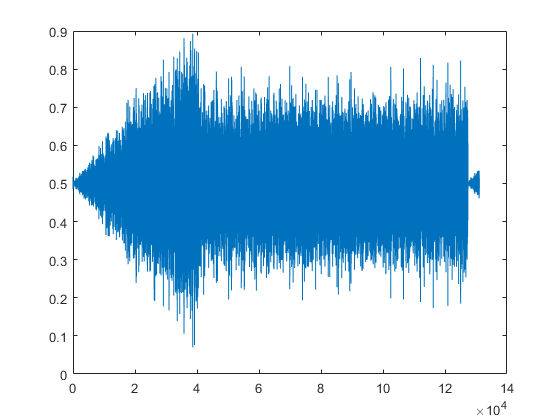

plot(V2)


tic

% Normalize the input and output training data to [0 1]
input = V1(40001:end);
output = V2(40001:end);

% histogram(input)
% histogram(output)

% Normalize the input and output test data to [0 1]
tinput = V1(1:40000);
toutput = V2(1:40000);


% Choose the lags for the input and output

inlags=[1 2 3 4 8];
outlags=[0 1 2 4 8];

% %  for prediction
% inlags=[1 2];
% outlags=[0 1 2 3 4];


Split test and training set

% % Features are lagged inputs and outputs

[featurez,zeta,tfeaturez,yt] = lagfeatures(input,tinput,output,toutput,inlags,outlags);

Construct B-spline basis vectors


[N, d]=size(featurez); % Number of samples and features

n = 3;                  %Degree B-spline
m = 1;                  %Number of knot intervals
In = n+m;               %Number of B-splines



Initialize tensor train

% Choose TT-ranks
maxrank = 8;

% % for prediction
% maxrank = 5;

r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));



Cross validation for tuning lambda

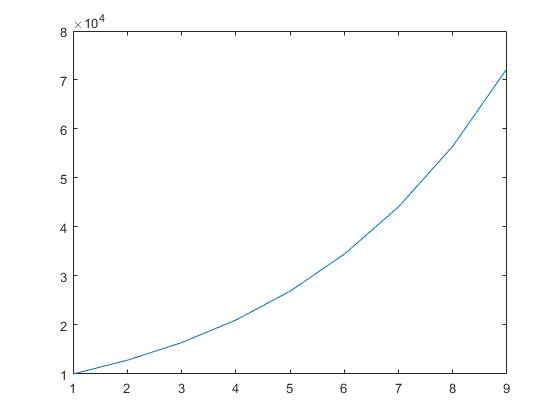

difforder=2;

MAXITR = d;

nselect = floor(logspace(log10(10000/N),-0.1,MAXITR)*N);
plot(nselect)


LAM = logspace(-1,-8,10);


for period = 1:numel(LAM)

    lambda = LAM(period);
    
for trial = 1:3

tselc = (1:5000)+(trial-1)*5000;
selc = setdiff(1:length(featurez),tselc);

fold = featurez(selc,:);
tfold = featurez(tselc,:);

Nf= size(fold, 1);

unf = basisvectors(fold,n,m);

for initial = 1:1
[TNf,Vmf,Vpf] = initTT(unf,r,d);

[TN,~,~,~,~] = optimTT(TNf,Vmf,Vpf,unf,zeta(selc),MAXITR,nselect,lambda,difforder);
disp(1)
[simoutput] = simnarx(TN,input(tselc),output(tselc),inlags,outlags,n,m);
RMSE_S(period,trial,initial) = sqrt(immse(10*output(tselc),10*simoutput));

yhat = evalspline(TN,tfold,n,m);
RMSE_P(period,trial,initial) = sqrt(immse(10*yhat,10*zeta(tselc)));
end
end
end

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1

     1



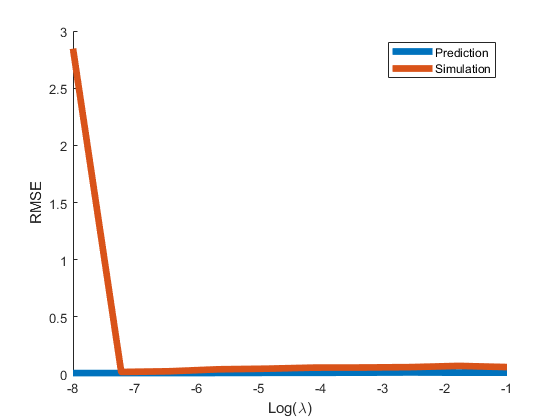


figure
hold on
% plot(RMSE_P)
% plot(RMSE_S)
plot(log10(LAM),squeeze(mean(RMSE_P,2)),"LineWidth",5)
% plot(squeeze(median(RMSE_P,2)),"LineWidth",5)
plot(log10(LAM),mean(RMSE_S,2),"LineWidth",5)
hold off
legend('Prediction', 'Simulation')
xlabel('Log(\lambda)')
ylabel('RMSE')


% scatter(mean(RMSE_P,2),mean(RMSE_S,2))
% scatter(median(RMSE_P,2),median(RMSE_S,2))

% [~,hyp] = min(median(median(RMSE_P,2),3));
[~,hyp] = min(mean(mean(RMSE_P,2),3));
% [~,hyp] = min(mean(mean(RMSE_S,2),3));
lambda = LAM(hyp)

lambda = 1.0000e-08



% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);

% Initialize Tensor Train and Vp and Vm
[TN,Vm,Vp] = initTT(un,r,d);


Optimize TT cores

difforder=1;
% lambda = 4.6416e-07 %from cross val
% lambda = 2e-07
% lambda = 10^-6;

MAXITR = d;

tic
[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,difforder);
toc

Elapsed time is 4.137646 seconds.


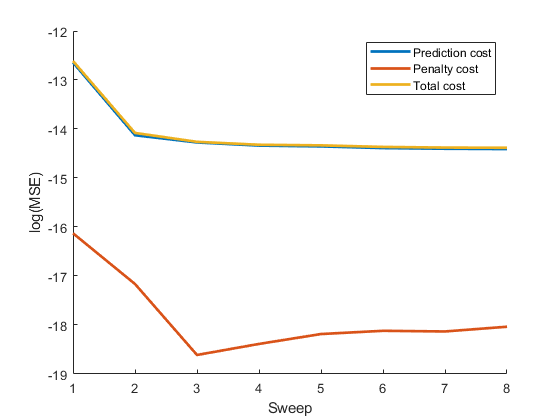


figure
hold on
plot(log(res1),'linewidth',2)
plot(log(res2),'linewidth',2)
plot(log(res1+res2),'linewidth',2)
hold off
legend('Prediction cost', 'Penalty cost', 'Total cost')
xlabel('Sweep')
ylabel('log(MSE)')


trainerror = res1(end);


t1 = res1+res2

t1 = 	1.0e+-5 *

    0.3330    0.0767    0.0640    0.0603    0.0596    0.0577    0.0569    0.0567


t2 = res1+res2

t2 = 	1.0e+-5 *

    0.3330    0.0767    0.0640    0.0603    0.0596    0.0577    0.0569    0.0567


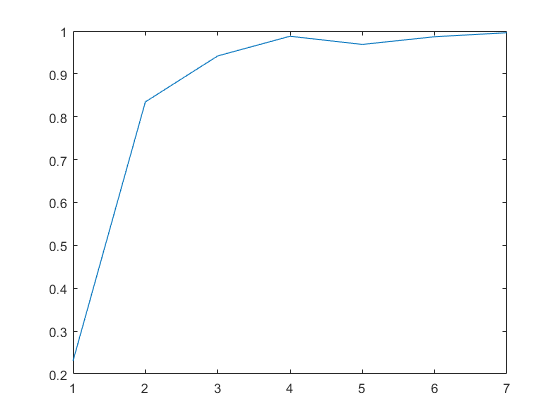


plot(t1(2:end)./t2(1:end-1))

Prediction Test data


yhat = evalspline(TN,tfeaturez,n,m);
erboi = (yhat-yt);
% histogram((erboi)');
VAF = 1-var(erboi)/var(yt)

VAF = 0.9999

RMSE_Pt = sqrt(immse(0.7*yhat,0.7*yt))

RMSE_Pt = 5.6049e-04

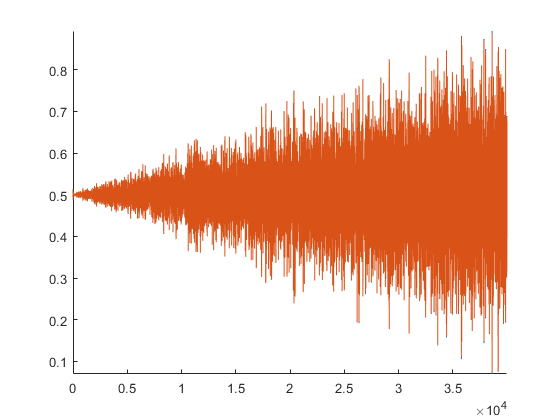


%  Visualize errors

figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 inf -inf inf])

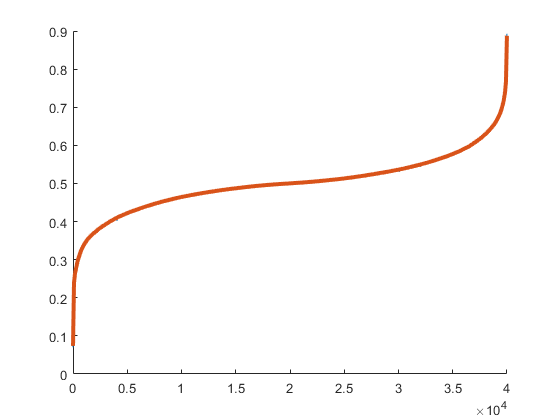


[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off

Simulation Test data

[simoutput] = simnarx(TN,tinput,toutput,inlags,outlags,n,m);




fig = figure

fig =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 20
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


hold on
plot(0.7*(toutput-0.5),'linewidth',1)
plot(0.7*(simoutput-0.5),'linewidth',1)
plot(0.7*(toutput)-0.7*simoutput,'linewidth',2)
hold off

beginz = max(outlags(end),inlags(end))+1;
RMSE_St = sqrt(immse(0.7*toutput(beginz:end),0.7*simoutput(beginz:end)))

RMSE_St = 0.0011

toc

Elapsed time is 509.509508 seconds.


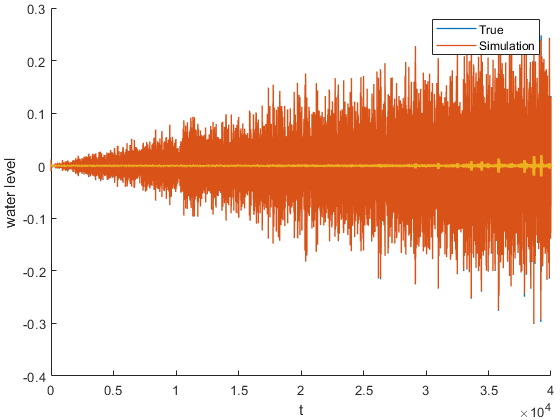

legend('True', 'Simulation')
xlabel('t')
ylabel('water level')

T = get(gca,'tightinset');
set(gca,'position',[T(1) T(2) 1-T(1)-T(3) 1-T(2)-T(4)]);
print(fig,'figures/silversim','-depsc')

Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %compression ratio

Compression: 0.0059814
